# Part 3: Find parameters for optima

In this doc: Yields & rates for a variety of initial cellulose conditions

Analysis: alpha below a certain point results in complete conversion but not sustained growth.

Todo? Calculate enzyme secretion rate at each step by checking the biomass delta * alpha

%Generate/load the data
if ~exist('remcfg','var')
    load remoteconfig;
end

%params from anaerobic/Comets_2.8.0/mannose/dat2.m
%maint as objective, no enzyme in maint, init with mannose 5%
args.p3.v.alpha = 0.0043;  
args.p3.v.km_cel = 0.1004; 
args.p3.v.kcat_cel = 38.8244;

%reduce initial cellulose to reflect incomplete conversion
args.p3.v.initcellulose = args.default.v.initcellulose * 0.27;
v_default.initcellulose = args.p3.v.initcellulose;

args.p3.variableInitEnzyme = true;
args.p3.variableInitEnzyme = false;
args.p3.v.initenzyme = 0;%args.p3.v.initialpop * 10^-3.5;

args.p3.enzInMaint = false;
args.p3.v.addEnzymeToMaint = args.p3.enzInMaint;

args.p3.v.maxcycles = 2000;

if runPart3
    args.p3.v_default = v_default;
    layouts3 = part3_generation_remote(args.p3);
    [layouts3,remcfg] = runCometsRemotely(layouts3,remcfg);
else
    if ~exist('dat3','var')
        load([datadir '\dat3_litParams.mat']);
    end
end

% %Temp 3/11/2020
% remcfg.batchnum = '200309132634';    
% 
% for i = 1:length(layouts3)
%     layouts3{i}.params.biomassLogName = 'biomass.m';
%     layouts3{i}.params.mediaLogName = 'media.m';
% end
% 
% % % layouts3_all = layouts3;
% % % layouts3 = layouts3(1:230);
% %error loading media for log 237
% %all layouts 237+ need to be run again

if ~exist('dat3','var')
    dat3 = part3_parseRemoteResults(layouts3,remcfg.batchnum);
    layouts3 = dat3.layout;
    [nrows,~] = size(dat3);
    dat3.layout = cell(nrows,1);
    dat3.enzymeInMaint = repmat(args.p3.v.addEnzymeToMaint,nrows,1);
    dat3.variableInitEnzyme = repmat(args.p3.variableInitEnzyme,nrows,1);
end

Loading Media File ./log_1/media.m
Loading Media File ./log_2/media.m
Loading Media File ./log_3/media.m
Loading Media File ./log_4/media.m
Loading Media File ./log_5/media.m
Loading Media File ./log_6/media.m
Loading Media File ./log_7/media.m
Loading Media File ./log_8/media.m
Loading Media File ./log_9/media.m
Loading Media File ./log_10/media.m
Loading Media File ./log_11/media.m
Loading Media File ./log_12/media.m
Loading Media File ./log_13/media.m
Loading Media File ./log_14/media.m
Loading Media File ./log_15/media.m
Loading Media File ./log_16/media.m
Loading Media File ./log_17/media.m
Loading Media File ./log_18/media.m
Loading Media File ./log_19/media.m
Loading Media File ./log_20/media.m
Loading Media File ./log_21/media.m
Loading Media File ./log_22/media.m
Loading Media File ./log_23/media.m
Loading Media File ./log_24/media.m
Loading Media File ./log_25/media.m
Loading Media File ./log_26/media.m
Loading Media File ./log_27/media.m
Loading Media File ./log_28/media.m
L

%filter out rows which didn't grow (by doubling its biomass)
filter1 = true;
filter1 = false;
[nrows,~] = size(dat3);
if ~exist('dat3_allrows','var') %first, grab a backup
    dat3.layout = zeros(nrows,1);
    dat3_allrows = dat3;
% else
%     dat3.layout = zeros(nrows,1);
%     dat3_allrows = unique(vertcat(dat3_allrows,dat3),'rows');
end

% meandelta = zeros(nrows,1);
% for i = 1:nrows
%     meandelta(i) = mean(dat3.biomass_delta{i});
% end
% dat3 = dat3(meandelta ~= 0,:);
growers = zeros(nrows,1);
for i = 1:nrows
    if dat3.biomass{i}(1) < max(dat3.biomass{i})/2
        growers(i) = true;
    end
end
nongrowers = ~growers;
dat3.did_grow = growers;
if filter1
    dat3 = dat3(logical(growers),:);
end

%filter out rows which didn't achieve complete cellulose conversion
filter2 = true;
filter2 = false;
filter2_threshold = 0.01;
[nrows,~] = size(dat3);
if ~exist('dat3_allrows','var') %first, grab a backup
    dat3.layout = zeros(nrows,1);
    dat3_allrows = dat3;
end
incomplete_conversion = zeros(nrows,1);
for i = 1:nrows
    if dat3.cellulose_amt{i}(end) > filter2_threshold
        incomplete_conversion(i) = true;
    end
end
dat3.incomplete_conversion = incomplete_conversion;
if filter2
    dat3 = dat3(~incomplete_conversion,:);
end

%keep the longest-running row for each cellulose/alpha pair
filter3 = true;
if ~ismember('runtime',dat3.Properties.VariableNames)
    dat3.runtime = cellfun(@(x) max(x),dat3.t);
end
filter3_redundant_rows = 0;
alphas = unique(dat3.alpha);
initcels = unique(dat3.initcel);
[nrows,~] = size(dat3);
if filter3
    t = table();
    for ia = 1:length(alphas)
        a = alphas(ia);
        for ic = 1:length(initcels)
            c = initcels(ic);
            idx = dat3.alpha == a & dat3.initcel == c;
            if sum(idx) > 0
                rows = dat3(idx,:);
                row = rows(rows.runtime == max(rows.runtime),:);
                row = row(1,:);
                t = vertcat(t,row);
            end
        end
    end
    [trows,~] = size(t);
    filter3_redundant_rows = nrows - trows;
    dat3 = t;
end

**Cellulolysis proceeds at the desired rate**

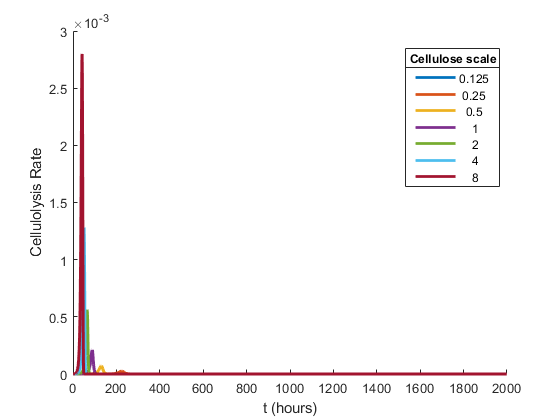

%KM Plots
xmax = args.p3.v.maxcycles;
kmdat = dat3(dat3.kcat_cel == mode(dat3.kcat_cel),:);
%kmdat = kmdat(kmdat.alpha == mode(kmdat.alpha),:);
kmdat = kmdat(kmdat.alpha == 10^(-2.75),:);
kmdat = kmdat(kmdat.alpha == mode(kmdat.alpha),:);
kmdat = sortrows(kmdat,'km_cel');

figure()
hold on;
[nrows,~] = size(kmdat);
for i = 1:nrows
    plot(kmdat.t{i}(1:end-1),-kmdat.cellulose_delta{i},'linewidth',2);
end
hold off;
%plot(kmdat.t{1}(1:end-1),-kmdat.cellulose_delta{1},kmdat.t{2}(1:end-1),-kmdat.cellulose_delta{2},kmdat.t{3}(1:end-1),-kmdat.cellulose_delta{3});
xlabel('t (hours)');
ylabel('Cellulolysis Rate');
xlim([0 xmax])
leg = legend(num2str(kmdat.celscale),'location','best');
ltitle = get(leg,'title');
set(ltitle,'String','Cellulose scale');

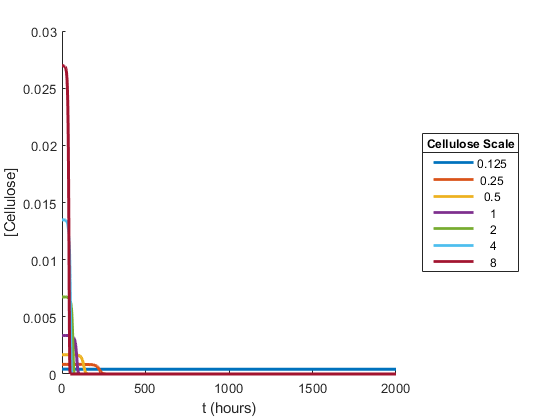

figure();
hold on;
for i = 1:nrows
    plot(kmdat.t{i}(1:end),kmdat.cellulose_amt{i},'linewidth',2);
end
hold off;
%plot(kmdat.t{1},kmdat.cellulose_amt{1},kmdat.t{2},kmdat.cellulose_amt{2},kmdat.t{3},kmdat.cellulose_amt{3});
xlabel('t (hours)');
ylabel('[Cellulose]');
leg = legend(num2str(kmdat.celscale),'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Cellulose Scale');
xlim([0 xmax])

%print the current figure (before we change the scale in the next lines)
copyobj(gca,figure);

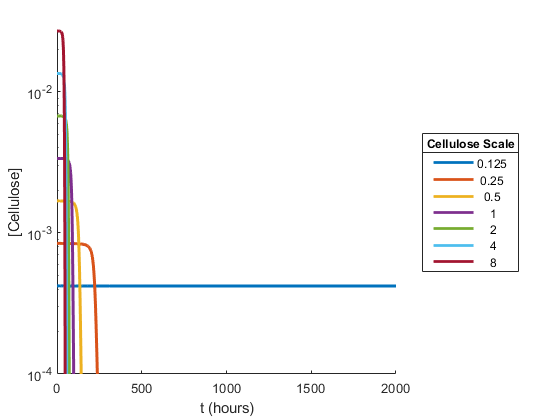


set(gca,'Yscale','log');
ylim([1e-4,max(kmdat.initcel)]);
leg = legend(num2str(kmdat.celscale),'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Cellulose Scale');

%add g_cellulose column
dat3.g_cellulose = dat3.initcel * args.p3.v.glcpercellulose * 180.156 / 1000;


figure();
plot(kmdat.cellulose_amt{1}(1:end-1),-kmdat.cellulose_delta{1},'-b',kmdat.cellulose_amt{2}(1:end-1),-kmdat.cellulose_delta{2},'-r',kmdat.cellulose_amt{3}(1:end-1),-kmdat.cellulose_delta{3},'-g')
xlabel('[Cellulose]');
ylabel('Cellulolysis Rate');
leg = legend(num2str(kmdat.km_cel),'location','best');

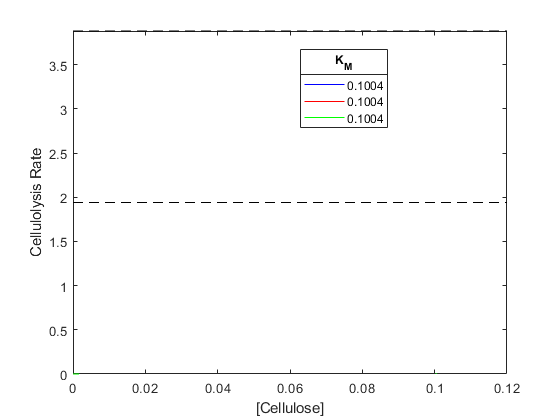

ltitle = get(leg,'title');
set(ltitle,'String','K_M');
hold on;
%indicate the half-saturation points and the theoretical max kcat
plot([kmdat.km_cel(1) kmdat.km_cel(1)],[0 .011],':b','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(1)/(1+kmdat.km(1)) .1*kmdat.kcat(1)/(1+kmdat.km(1))],'-.b','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(1)*kmdat.km(1)/(kmdat.km(1)+kmdat.km(1)) .1*kmdat.kcat(1)*kmdat.km(1)/(kmdat.km(1)+kmdat.km(1))],'-.b','HandleVisibility','off');
rline = refline(0, (.1 * kmdat.kcat_cel(1) * kmdat.km_cel(1))/(2 * kmdat.km_cel(1)));
rline.LineStyle = '--';
rline.Color = 'k';
rline.HandleVisibility = 'off';
rline = refline(0, (.1 * kmdat.kcat_cel(1)));
rline.LineStyle = '--';
rline.Color = 'k';
rline.HandleVisibility = 'off';
plot([kmdat.km_cel(2) kmdat.km_cel(2)],[0 .011],':r','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(2)/(1+kmdat.km(2)) .1*kmdat.kcat(2)/(1+kmdat.km(2))],'-.r','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(2)*kmdat.km(2)/(kmdat.km(2)+kmdat.km(2)) .1*kmdat.kcat(2)*kmdat.km(2)/(kmdat.km(2)+kmdat.km(2))],'-.r','HandleVisibility','off');
% rline = refline(0, (.1 * kmdat.kcat(2) * kmdat.km(2))/(2 * kmdat.km(2)));
% rline.LineStyle = '--';
% rline.Color = 'r';
plot([kmdat.km_cel(3) kmdat.km_cel(3)],[0 .011],':g','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(3)/(1+kmdat.km(3)) .1*kmdat.kcat(3)/(1+kmdat.km(3))],'-.g','HandleVisibility','off');
%plot([0 1],[.1*kmdat.kcat(3)*kmdat.km(3)/(kmdat.km(3)+kmdat.km(3)) .1*kmdat.kcat(3)*kmdat.km(3)/(kmdat.km(3)+kmdat.km(3))],'-.g','HandleVisibility','off');
% rline = refline(0, (.1 * kmdat.kcat(3) * kmdat.km(3))/(2 * kmdat.km(3)));
% rline.LineStyle = '--';
% rline.Color = 'g';

%xlim([0 3]);
%ylim([0 0.011]);

hold off;


%KCAT PLOTS ------------------------------------------
kcatdat = dat3(dat3.km_cel == mode(dat3.km_cel),:);
kcatdat = sortrows(kcatdat,'kcat_cel');

plot(kcatdat.t{1}(1:end-1),-kcatdat.cellulose_delta{1},kcatdat.t{2}(1:end-1),-kcatdat.cellulose_delta{2},kcatdat.t{3}(1:end-1),-kcatdat.cellulose_delta{3});
xlabel('t (hours)');
ylabel('Cellulolysis Rate');
%leg = legend(num2str(kcatdat.kcat_cel),'location','best');
leg = legend(num2str(kcatdat.g_cellulose),'location','best');

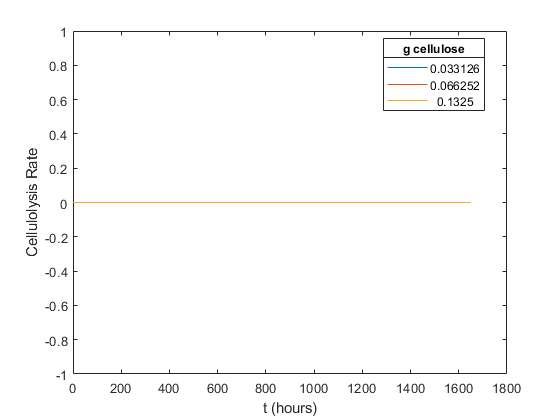

ltitle = get(leg,'title');
%set(ltitle,'String','k_c_a_t');
set(ltitle,'String','g cellulose');

subplot(1,2,1)
plot(kcatdat.t{1},kcatdat.cellulose_amt{1},kcatdat.t{2},kcatdat.cellulose_amt{2},kcatdat.t{3},kcatdat.cellulose_amt{3});
xlabel('t (hours)');
ylabel('[Cellulose]');
%leg = legend(num2str(kcatdat.kcat_cel),'location','best');
leg = legend(num2str(kcatdat.g_cellulose),'location','best');

ltitle = get(leg,'title');
%set(ltitle,'String','k_c_a_t');
set(ltitle,'String','g cellulose');
subplot(1,2,2)
plot(kcatdat.cellulose_amt{1}(1:end-1),-kcatdat.cellulose_delta{1},kcatdat.cellulose_amt{2}(1:end-1),-kcatdat.cellulose_delta{2},kcatdat.cellulose_amt{3}(1:end-1),-kcatdat.cellulose_delta{3})
xlabel('[Cellulose]');
ylabel('Cellulolysis Rate');
%leg = legend(num2str(kcatdat.kcat_cel),'location','best');
leg = legend(num2str(kcatdat.g_cellulose),'location','best');

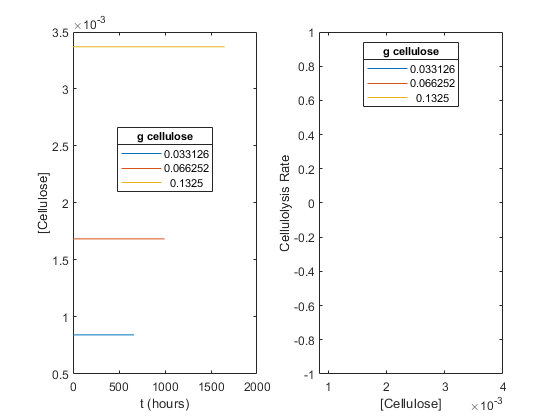

ltitle = get(leg,'title');
%set(ltitle,'String','k_c_a_t');
set(ltitle,'String','g cellulose');

g_avicel_per_mol =  (180.156 - 17) * args.p3.v.glcpercellulose;
dat3.yield = (dat3.biomass_max - cellfun(@(x) x(1),dat3.biomass))  ./ (dat3.initcel * g_avicel_per_mol / 1000);
dat3.g_cellulose = dat3.initcel * g_avicel_per_mol / 1000;

## **Find the alpha that produces the best yield**

dat3_partial = dat3(mod(log10(dat3.alpha),1) == .25,:);
initcelamts = unique(dat3_partial.initcel);
g_avicel = (initcelamts) * (180.156 - 17) * args.p3.v.glcpercellulose / 1000;
ic = initcelamts(1)

ic = 4.2134e-04

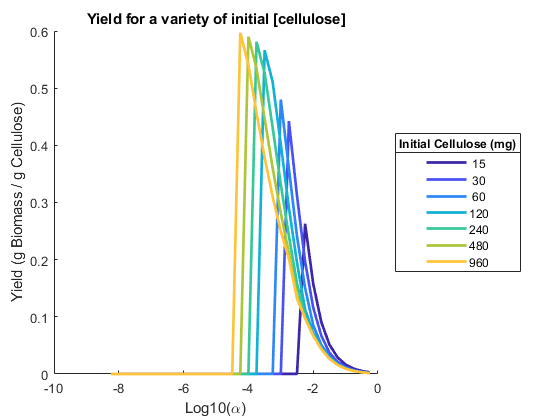

ydat = dat3_partial(dat3_partial.initcel == ic,:);

% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% %colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},ydat.biomass{i}/ydat.g_cellulose(i),'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Yield')
% hold off;
% title(['Initial Cellulose = ' num2str(g_avicel(1)) 'g']);
% 
% ic = initcelamts(ceil(length(initcelamts)/2))
% ydat = dat3_partial(dat3_partial.initcel == ic,:);
% 
% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% %colors = parula(1+nrows);
% for i = 1:nrows
%     i
%     plot(ydat.t{i},ydat.biomass{i}/ydat.g_cellulose(i),'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Yield')
% hold off;
% title(['Initial Cellulose = ' num2str(g_avicel(ceil(length(initcelamts)/2))) 'g']);
% 
% 
% ic = initcelamts(end)
% ydat = dat3_partial(dat3_partial.initcel == ic,:);
% 
% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% %colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},ydat.biomass{i}/ydat.g_cellulose(i),'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Yield')
% hold off;
% title(['Initial Cellulose = ' num2str(g_avicel(length(initcelamts))) 'g']);

% ic = initcelamts(4)
% ydat = dat3_partial(dat3_partial.initcel == ic,:);
% 
% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},ydat.biomass{i},'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Yield')
% hold off;
% 
% ic = initcelamts(5)
% ydat = dat3_partial(dat3_partial.initcel == ic,:);
% 
% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},ydat.biomass{i},'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Yield')
% hold off;

%plot yield / a for each cel amount
f = figure();
hold on;

colors = parula(1+length(initcelamts));
besta_yield = zeros(length(initcelamts),1);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    plot(log10(d.alpha),d.yield,'color',colors(i,:),'linewidth',2);
    
    besta_yield(i) = mode(log10(d.alpha(d.biomass_max==max(d.biomass_max))));
    %scatter(besta_yield(i),max(d.yield),50,colors(i,:),'+','HandleVisibility','off');
end
hold off;
ylabel('Yield (g Biomass / g Cellulose)');
xlabel('Log10(\alpha)');
leg = legend(num2str(1000 * g_avicel),'location','eastoutside');
title(leg,'Initial Cellulose (mg)')
title('Yield for a variety of initial [cellulose]')

%set(gca,'yscale','log')

%ylim([0 .3]);
%xlim([-7 0]);

if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_yieldfig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_yield.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_yield.eps');%for LaTeX
end

% xlim([-10 -2.00])
% ylim([0.005 0.1000])
%ylim([1e-1, 1e1])

%Find the best alpha for each cellulose amount
f = scatter(initcelamts,besta_yield)

f =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [4.2134e-04 8.4268e-04 0.0017 0.0034 0.0067 0.0135 0.0270]
              YData: [-2.2500 -2.7500 -3 -3.5000 -3.7500 -4 -4.2500]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


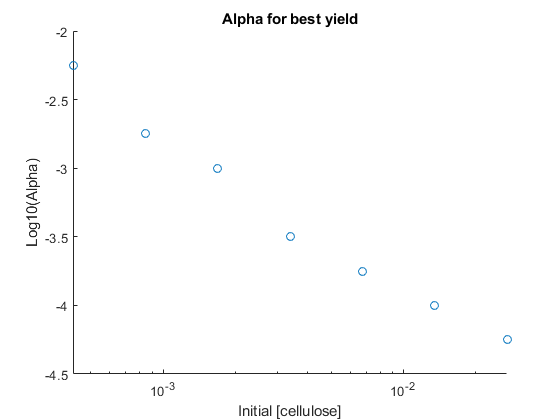

%ylim([-10,-5]);
ylabel('Log10(Alpha)')
xlabel('Initial [cellulose]');
%refline(0,-9);
title('Alpha for best yield');
set(gca,'Xscale','log')


if overwritefiles
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_yield_scatter.fig');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_yield_scatter.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_yield_scatter.eps');%for LaTeX
end

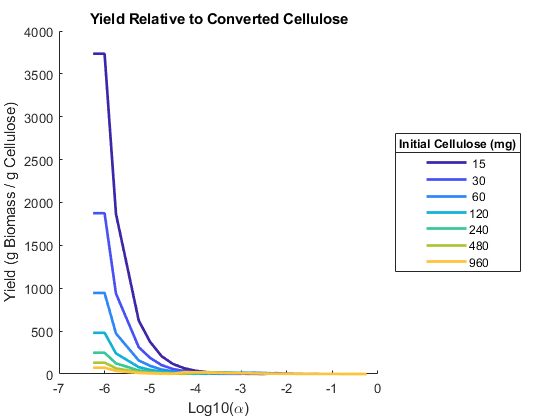

%Find the yield per gram cellulose CONVERTED instead of total
figure();
hold on;

colors = parula(1+length(initcelamts));
besta_yield_converted = zeros(length(initcelamts),1);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    for j = 1:length(d.biomass)
        d.biomass_delta_total(j) = sum(d.biomass_delta{j});
        d.cellulose_delta_total(j) = sum(d.cellulose_delta{j});
        d.yield_per_converted_cellulose(j) = d.biomass_delta_total(j) / -d.cellulose_delta_total(j);
    end
    plot(log10(d.alpha),d.yield_per_converted_cellulose,'color',colors(i,:),'linewidth',2);
    
    besta_yield_converted(i) = mode(log10(d.alpha(d.biomass_max==max(d.biomass_max))));
    %scatter(besta_yield(i),max(d.yield),50,colors(i,:),'+','HandleVisibility','off');
end
hold off;
ylabel('Yield (g Biomass / g Cellulose)');
xlabel('Log10(\alpha)');
leg = legend(num2str(1000 * g_avicel),'location','eastoutside');
title(leg,'Initial Cellulose (mg)')
title('Yield Relative to Converted Cellulose')

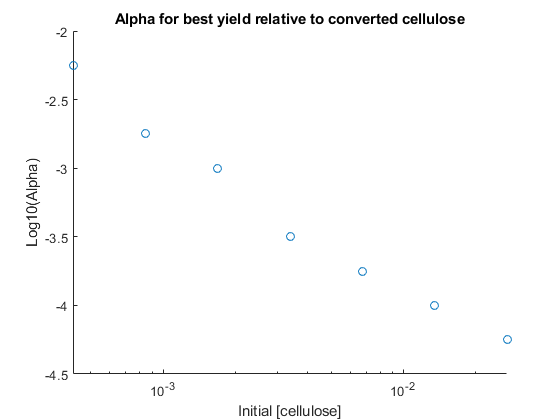

%set(gca,'yscale','log')

%Find the best alpha for each cellulose amount
scatter(initcelamts,besta_yield)
%ylim([-10,-5]);
ylabel('Log10(Alpha)')
xlabel('Initial [cellulose]');
%refline(0,-9);
title('Alpha for best yield relative to converted cellulose');
set(gca,'Xscale','log')

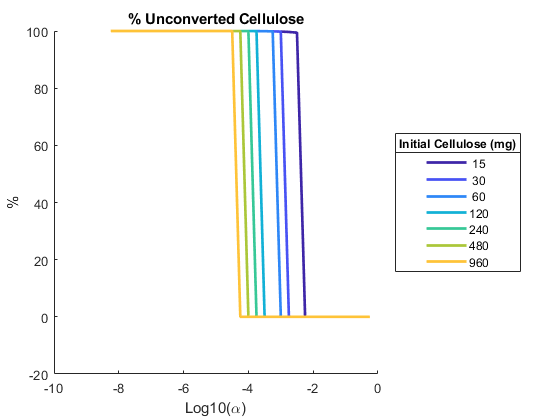


%check how much cellulose remained in each case
figure();
hold on;
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    for j = 1:length(d.biomass)
        cellulose_init = d.cellulose_amt{j}(1);
        cellulose_delta_total = sum(d.cellulose_delta{j});
        d.cellulose_remaining(j) = cellulose_init + cellulose_delta_total;
        d.cellulose_remaining_pct(j) = 100 * d.cellulose_remaining(j) / cellulose_init;
    end
    plot(log10(d.alpha),d.cellulose_remaining_pct,'color',colors(i,:),'linewidth',2);
end
ylabel('%');
xlabel('Log10(\alpha)');
leg = legend(num2str(1000 * g_avicel),'location','eastoutside');
title(leg,'Initial Cellulose (mg)')
title('% Unconverted Cellulose')

## %Find the alpha that produces the best growth rate

dat3_partial = dat3(mod(log10(dat3.alpha),1) == 0,:);

%temp
% dat3_partial = dat3;

initcelamts = unique(dat3_partial.initcel);
g_avicel = (initcelamts/1000) * (180.156 - 17) * args.p3.v.glcpercellulose;

ic = initcelamts(1)

ic = 4.2134e-04

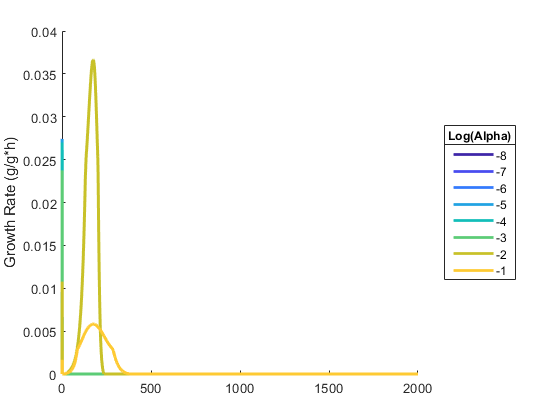

ydat = dat3_partial(dat3_partial.initcel == ic,:);

% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},[0; ydat.biomass_delta{i}],'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Growth Rate (g/h)')
% hold off;

figure();
hold on;
[nrows,~] = size(ydat);
colors = parula(1+nrows);
colors = parula(1+nrows);
for i = 1:nrows
    r = ydat.biomass_delta{i} ./ ydat.biomass{i}(1:end-1);
    plot(ydat.t{i},[0; r],'color',colors(i,:),'linewidth',2);
end
leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
title(leg,'Log(Alpha)')
ylabel('Growth Rate (g/g*h)')
hold off;


ic = initcelamts(2)

ic = 8.4268e-04

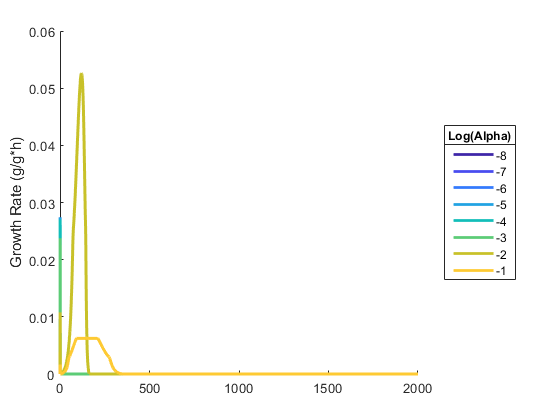

ydat = dat3_partial(dat3_partial.initcel == ic,:);

% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},[0; ydat.biomass_delta{i}],'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Growth Rate (g/h)')
% hold off;

figure();
hold on;
[nrows,~] = size(ydat);
colors = parula(1+nrows);
colors = parula(1+nrows);
for i = 1:nrows
    r = ydat.biomass_delta{i} ./ ydat.biomass{i}(1:end-1);
    plot(ydat.t{i},[0; r],'color',colors(i,:),'linewidth',2);
end
leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
title(leg,'Log(Alpha)')
ylabel('Growth Rate (g/g*h)')
hold off;


ic = initcelamts(3)

ic = 0.0017

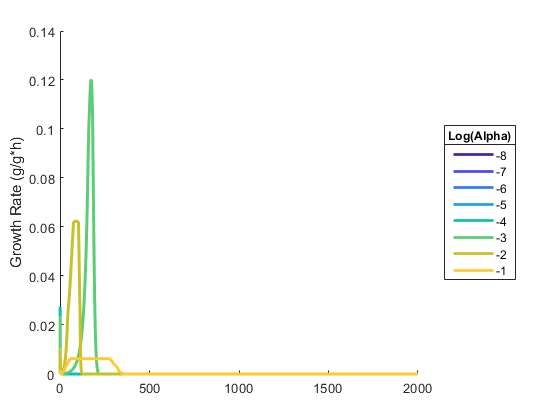

ydat = dat3_partial(dat3_partial.initcel == ic,:);

% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},[0; ydat.biomass_delta{i}],'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Growth Rate (g/h)')
% hold off;

figure();
hold on;
[nrows,~] = size(ydat);
colors = parula(1+nrows);
colors = parula(1+nrows);
for i = 1:nrows
    r = ydat.biomass_delta{i} ./ ydat.biomass{i}(1:end-1);
    r = [0; r];
    n = min(length(r),length(ydat.t{i}));
    plot(ydat.t{i}(1:n), r(1:n),'color',colors(i,:),'linewidth',2);
end
leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
title(leg,'Log(Alpha)')
ylabel('Growth Rate (g/g*h)')
hold off;

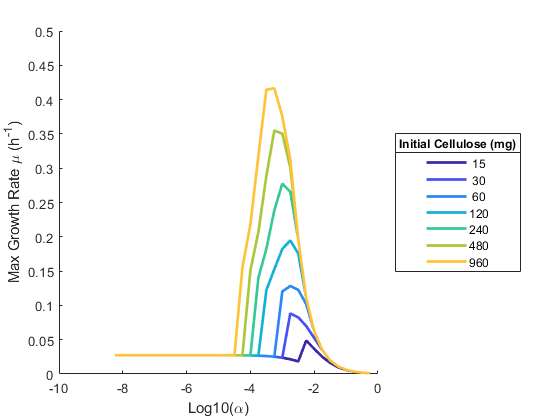

% ic = initcelamts(4)
% ydat = dat3_partial(dat3_partial.initcel == ic,:);
% 
% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},[0; ydat.biomass_delta{i}],'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Growth Rate')
% hold off;
% 
% ic = initcelamts(5)
% ydat = dat3_partial(dat3_partial.initcel == ic,:);
% 
% figure();
% hold on;
% [nrows,~] = size(ydat);
% colors = parula(1+nrows);
% for i = 1:nrows
%     plot(ydat.t{i},[0; ydat.biomass_delta{i}],'color',colors(i,:),'linewidth',2);
% end
% leg = legend(num2str(log10(ydat.alpha)),'location','eastoutside');
% title(leg,'Log(Alpha)')
% ylabel('Growth Rate')
% hold off;

% %plot rate / a for each cel amount
% figure();
% hold on;
% besta_rate = zeros(size(initcelamts));
% maxrate = 0;
% colors = parula(1+length(initcelamts));
% %colors = parula(1+nrows);
% for i = 1:length(initcelamts)
%     amt = initcelamts(i);
%     d = dat3(dat3.initcel == amt,:);
%     r = cellfun(@(x) max(x),d.biomass_delta);
%     plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
%     maxrate = max([maxrate;r]);
%     besta_rate(i) = mode(log10(d.alpha(r==max(r))));
% end
% hold off;
% ylabel('Max Growth Rate (g/h)');
% xlabel('Log(Alpha)');
% leg = legend(num2str(g_avicel*1000),'location','eastoutside');
% title(leg,'Initial Cellulose (mmol)');
% set(gca,'yscale','log');
% 
% %Find the best alpha for each cellulose amount
% scatter(initcelamts,besta_rate)
% ylim([-10,0]);
% ylabel('Log(Alpha)')
% xlabel('Initial [cellulose]');
% refline(0,-9);
% title('Alpha for best rate (g/h)');
% set(gca,'xscale','log');

f = figure();
hold on;
besta_rate2 = zeros(size(initcelamts));
maxrate = 0;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    deltas = cell(nrows,1);
    for j = 1:nrows
        deltas{j} = d.biomass_delta{j} ./ d.biomass{j}(1:end-1); 
    end
    r = cellfun(@(x) max(x),deltas);
    plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
    maxrate = max([maxrate;r]);
    besta_rate2(i) = mode(log10(d.alpha(r==max(r))));
end
hold off;
ylabel('Max Growth Rate \mu (h^-^1)');
xlabel('Log10(\alpha)');
leg = legend(num2str(g_avicel*1000),'location','eastoutside');
title(leg,'Initial Cellulose (mg)');
%set(gca,'yscale','log');
ylim([0 .5]);

if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate.eps');%for LaTeX
end



%Find the best alpha for each cellulose amount
f = scatter(initcelamts,besta_rate2)

f =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [4.2134e-04 8.4268e-04 0.0017 0.0034 0.0067 0.0135 0.0270]
              YData: [-2.2500 -2.7500 -2.7500 -2.7500 -3 -3.2500 -3.2500]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


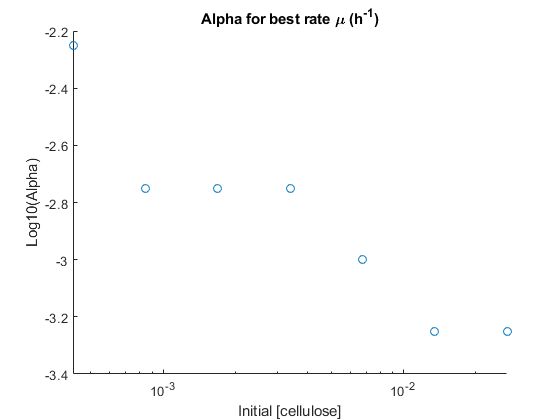

%ylim([-10,-5]);
ylabel('Log10(Alpha)')
xlabel('Initial [cellulose]');
%refline(0,-9);
set(gca,'Xscale','log');
title('Alpha for best rate \mu (h^-^1)');


if overwritefiles
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_scatter.fig');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_scatter.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_scatter.eps');%for LaTeX
end


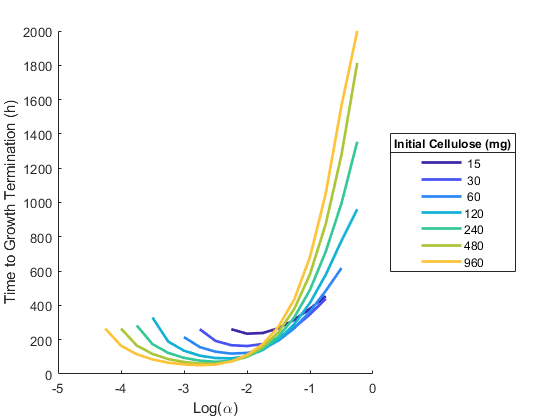

%Time to growth termination
f = figure();
hold on;
besta_finish = zeros(size(initcelamts));
mintime = 1000;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    r = nan(nrows,1);
    for j = 1:nrows
        isfinished = d.biomass{j} == d.biomass_max(j);
        %cut out rows that didn't grow (by doublings its biomass)
        idx = find(isfinished,1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            r(j) = t(idx);
        end
    end
    
    plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
    
    mintime = min([mintime;r]);
    besta_finish(i) = mode(log10(d.alpha(r==min(r))));
end
hold off;
ylabel('Time to Growth Termination (h)');
xlabel('Log(\alpha)');
leg = legend(num2str(g_avicel*1000),'location','eastoutside');
title(leg,'Initial Cellulose (mg)');

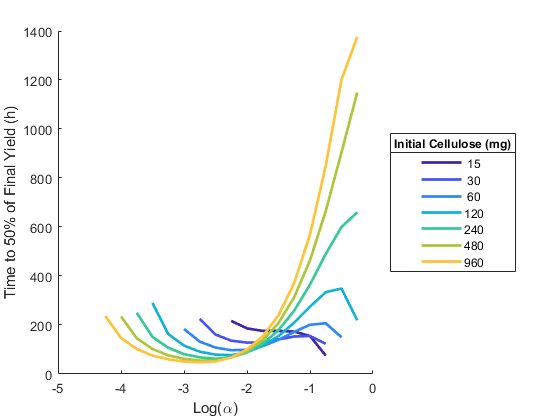

if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_timeToFinish.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_timeToFinish.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_timeToFinish.eps');%for LaTeX
end

%Time to half of final biomass yield
f = figure();
hold on;
besta_halfyield = zeros(size(initcelamts));
mintimehalf = 1000;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    r = nan(nrows,1);
    for j = 1:nrows
        isfinished = d.biomass{j} >= d.biomass_max(j)/2;
        %cut out rows that didn't grow (by doubling its biomass)
        idx = find(isfinished,1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            r(j) = t(idx);
        end
    end
    
    plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
    
    mintimehalf = min([mintimehalf;r]);
    besta_halfyield(i) = mode(log10(d.alpha(r==min(r))));
end
hold off;
ylabel('Time to 50% of Final Yield (h)');
xlabel('Log(\alpha)');
leg = legend(num2str(g_avicel*1000),'location','eastoutside');
title(leg,'Initial Cellulose (mg)');

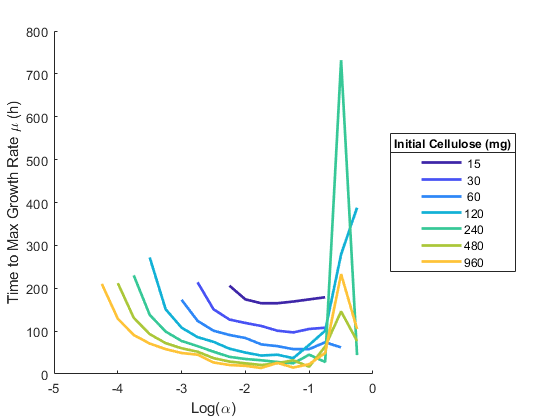

if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_timeToHalfYield.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_timeToHalfYield.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_timeToHalfYield.eps');%for LaTeX
end

%Time to peak growth rate
f = figure();
hold on;
maxrate = 0;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    deltas = cell(nrows,1);
    for j = 1:nrows
        deltas{j} = d.biomass_delta{j} ./ d.biomass{j}(1:end-1); 
    end
    r = cellfun(@(x) max(x),deltas);
    
    res = nan(nrows,1);
    for j = 1:nrows
        idx = find(deltas{j} == r(j),1);
        %cut out non-growing data
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            res(j) = t(idx);
        end
    end
    
    
    plot(log10(d.alpha),res,'color',colors(i,:),'linewidth',2);
    
end
hold off;
ylabel('Time to Max Growth Rate \mu (h)');
xlabel('Log(\alpha)');
leg = legend(num2str(g_avicel*1000),'location','eastoutside');
title(leg,'Initial Cellulose (mg)');

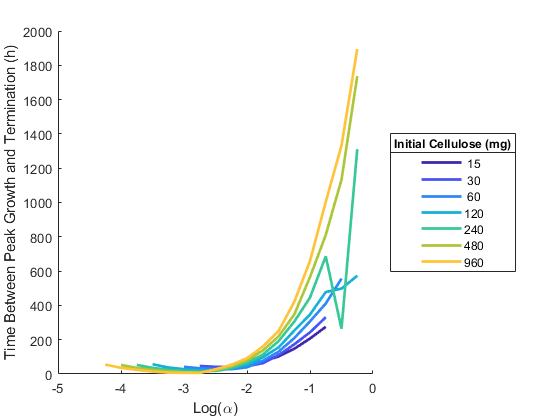

%set(gca,'yscale','log');
%ylim([0 .5]);
if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal_rate_timeToMaxGrowth.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal__rate_timeToMaxGrowth.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\optimal__rate_timeToMaxGrowth.eps');%for LaTeX
end

%Difference between max rate time and end of growth
f = figure();
hold on;
besta_finish = zeros(size(initcelamts));
mintime = 1000;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    rf = nan(nrows,1);
    for j = 1:nrows
        isfinished = d.biomass{j} == d.biomass_max(j);
        %cut out rows that didn't grow (by doubling its biomass)
        idx = find(isfinished,1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            rf(j) = t(idx);
        end
    end
    deltas = cell(nrows,1);
    for j = 1:nrows
        deltas{j} = d.biomass_delta{j} ./ d.biomass{j}(1:end-1); 
    end
    rd = cellfun(@(x) max(x),deltas);
    
    rr = nan(nrows,1);
    for j = 1:nrows
        idx = find(deltas{j} == rd(j),1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            rr(j) = t(idx);
        end
    end
    
    r = rf - rr;
    
    plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
    
end
hold off;
ylabel('Time Between Peak Growth and Termination (h)');
xlabel('Log(\alpha)');
leg = legend(num2str(g_avicel*1000),'location','eastoutside');
title(leg,'Initial Cellulose (mg)');

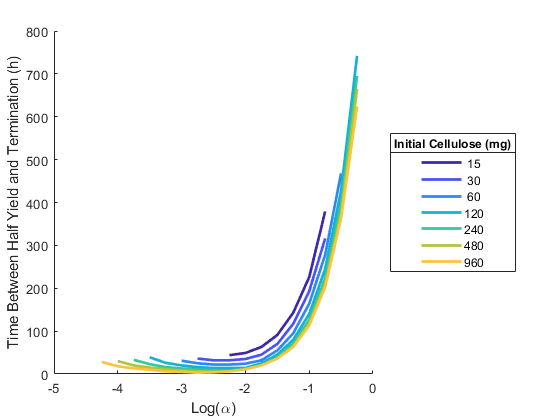


%Difference between half yield and end of growth
f = figure();
hold on;
besta_finish = zeros(size(initcelamts));
mintime = 1000;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    rf = nan(nrows,1);
    for j = 1:nrows
        isfinished = d.biomass{j} == d.biomass_max(j);
        %cut out rows that didn't grow
        idx = find(isfinished,1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            rf(j) = t(idx);
        end
    end
    rh = nan(nrows,1);
    for j = 1:nrows
        isfinished = d.biomass{j} >= d.biomass_max(j)/2;
        %cut out rows that didn't grow
        idx = find(isfinished,1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            rh(j) = t(idx);
        end
    end

    r = rf - rh;
    
    plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
    
end
hold off;
ylabel('Time Between Half Yield and Termination (h)');
xlabel('Log(\alpha)');
leg = legend(num2str(g_avicel*1000),'location','eastoutside');
title(leg,'Initial Cellulose (mg)');

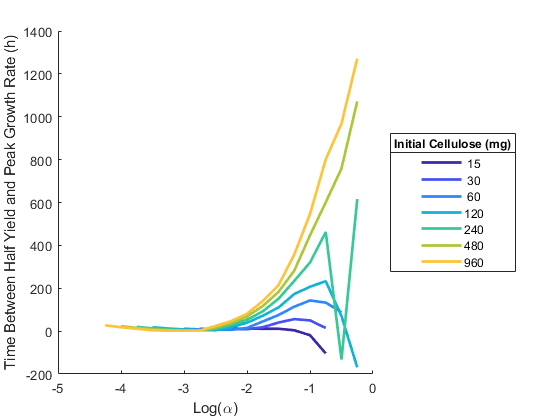



%Difference between half yield and peak growth rate
f = figure();
hold on;
besta_finish = zeros(size(initcelamts));
mintime = 1000;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
   
    rh = nan(nrows,1);
    for j = 1:nrows
        isfinished = d.biomass{j} >= d.biomass_max(j)/2;
        %cut out rows that didn't grow
        idx = find(isfinished,1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            rh(j) = t(idx);
        end
    end
     deltas = cell(nrows,1);
    for j = 1:nrows
        deltas{j} = d.biomass_delta{j} ./ d.biomass{j}(1:end-1); 
    end
    rd = cellfun(@(x) max(x),deltas);
    
    rr = nan(nrows,1);
    for j = 1:nrows
        idx = find(deltas{j} == rd(j),1);
        if d.biomass{j}(1) < d.biomass_max(j)/2
            t = d.t{j};
            rr(j) = t(idx);
        end
    end
    
    r = rh - rr;
    
    plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
    
end
hold off;
ylabel('Time Between Half Yield and Peak Growth Rate (h)');
xlabel('Log(\alpha)');
leg = legend(num2str(g_avicel*1000),'location','eastoutside');
title(leg,'Initial Cellulose (mg)');


% %compare the two methods
% figure();
% hold on;
% scatter(initcelamts,besta_rate,[],'r','filled','displayname','Biomass Delta');
% scatter(initcelamts,besta_rate2,[],'b','filled','displayname','Percent Increase');
% title('Alpha for best rate');
% ylim([-10,0]);
% set(gca,'xscale','log');
% leg = legend('location','best');
% xlabel('Initial [cellulose]');
% ylabel('Log(Alpha)');
% hold off;

## Compare best alpha for yield and rate

% scatter(besta_yield,besta_rate)
% hold on;
% lin = line([-9,-2],[-9,-2]);
% set(lin,'LineStyle','--')
% textdelta = .1;
scatterlabel = num2str(1000 * g_avicel);
% scatterlabel = {'1' '2' '3' '4' '5' '6' '7'};
% scatterlabel = {'15' '30' '60' '120' '240' '480' '960'};
% text(besta_yield + textdelta,besta_rate + textdelta, scatterlabel);
% xlim([-10 -5]);
% ylim([-10 -5]);
% %text(besta_yield + textdelta,besta_rate + textdelta, {'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'});
% hold off;
% xlabel('Best A for Yield (g/mmol Cel)');
% ylabel('Best A for Rate (g/h)');

colors = parula(1+length(scatterlabel));
colors = colors(1:length(scatterlabel),:);

f = scatter(besta_yield,besta_rate2,[],colors,'filled')

f =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 36
          LineWidth: 0.5000
              XData: [-2.2500 -2.7500 -3 -3.5000 -3.7500 -4 -4.2500]
              YData: [-2.2500 -2.7500 -2.7500 -2.7500 -3 -3.2500 -3.2500]
              ZData: [1×0 double]
              CData: [7×3 double]

  Show all properties


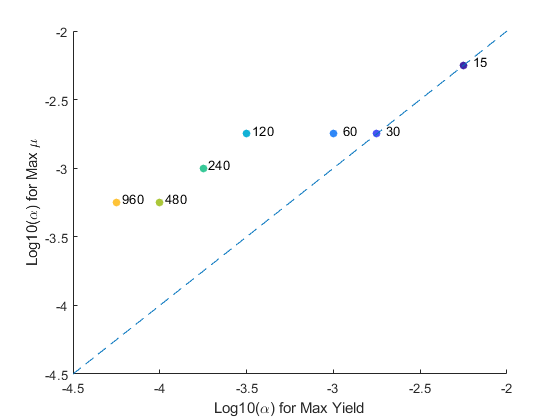

hold on;
lin = line([-4.5,-2],[-4.5,-2]);
set(lin,'LineStyle','--')
textdelta = .03;
text(besta_yield + textdelta,besta_rate2 + textdelta, scatterlabel);
%text(besta_yield + textdelta,besta_rate + textdelta, {'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'});
hold off;
xlabel('Log10(\alpha) for Max Yield');
ylabel('Log10(\alpha) for Max \mu');

%xlim([-10 -5]);
%ylim([-10 -5]);

if overwritefiles
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\alpha_comparison.fig');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\alpha_comparison.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\alpha_comparison.eps');%for LaTeX
end

% %best a for yield and growth in log10
% besta_yield_log10 = log10(pow2(besta_yield));
% besta_rate2_log10 = log10(pow2(besta_rate2));
% f = scatter(besta_yield_log10,besta_rate2_log10)
% hold on;
% lin = line([-4,-2.5],[-4,-2.5]);
% set(lin,'LineStyle','--')
% textdelta = .02;
% text(besta_yield_log10 + textdelta,besta_rate2_log10 + textdelta, scatterlabel);
% %text(besta_yield + textdelta,besta_rate + textdelta, {'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'});
% hold off;
% xlabel('Log(\alpha) for Max Yield');
% ylabel('Log(\alpha) for Max \mu');

% %plot rate and yield / a simultaneously for each cel amount
% figure();
% hold on;
% colors = parula(1+length(initcelamts));
% for i = 1:length(initcelamts)
%     amt = initcelamts(i);
%     d = dat3(dat3.initcel == amt,:);
%     r = cellfun(@(x) max(x),d.biomass_delta);
%     plot(log10(d.alpha),r/maxrate,'--','color',colors(i,:),'linewidth',2);
%     plot(log10(d.alpha),d.yield/max(dat3.yield),'color',colors(i,:),'linewidth',2);
% end
% hold off;
% ylabel('% Max');
% xlabel('Log(Alpha)');
% leg = legend(num2str(g_avicel),'location','eastoutside');


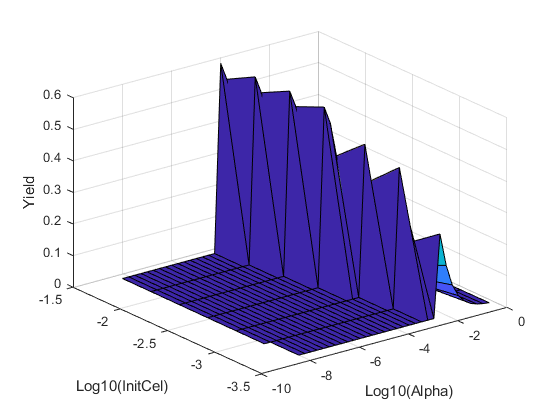

%3D Plots for the above

%Yield over alpha and initcel
[p,X,Y,Z] = surfArrays(log10(dat3.alpha),log10(dat3.initcel),dat3.yield);
xlabel('Log10(Alpha)')
ylabel('Log10(InitCel)')
zlabel('Yield')

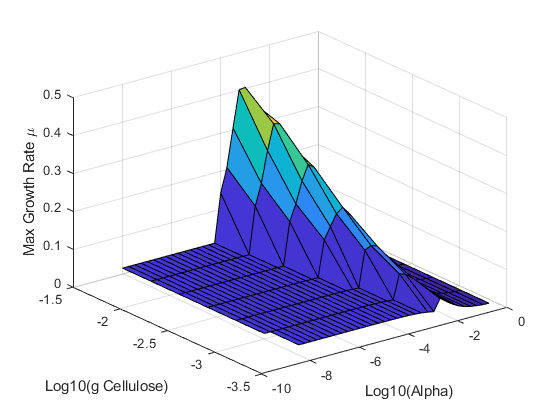


dat3.mu = cellfun(@(x,y) x./y(1:end-1),dat3.biomass_delta,dat3.biomass,'uniformoutput',false);
dat3.maxrate = cellfun(@(x) max(x),dat3.mu);
[p,X,Y,Z] = surfArrays(log10(dat3.alpha),log10(dat3.initcel),dat3.maxrate);
xlabel('Log10(Alpha)')
ylabel('Log10(g Cellulose)')
zlabel('Max Growth Rate \mu')

### Figure: Yield and growth rate for range of alphas

currentscale = 0.1250

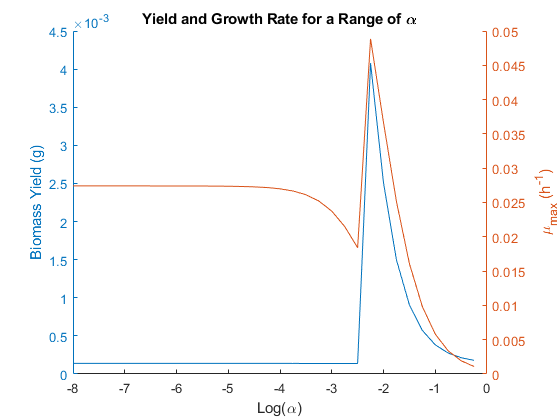

currentscale = 0.1250

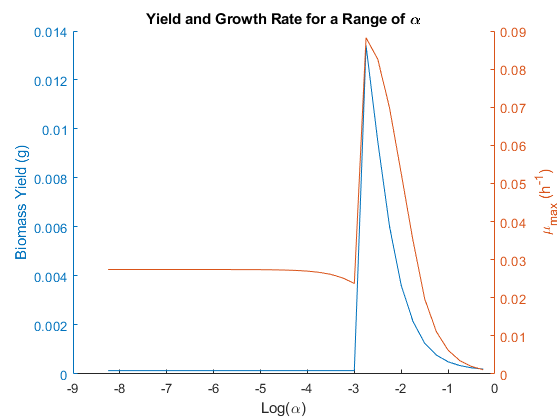

currentscale = 0.1250

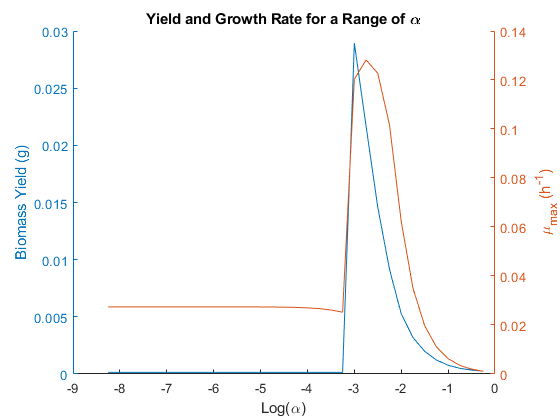

currentscale = 0.1250

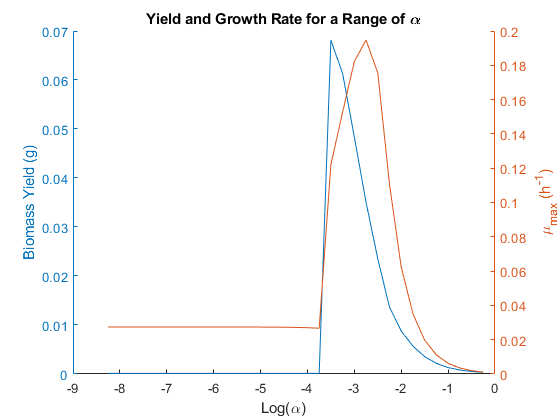

currentscale = 0.1250

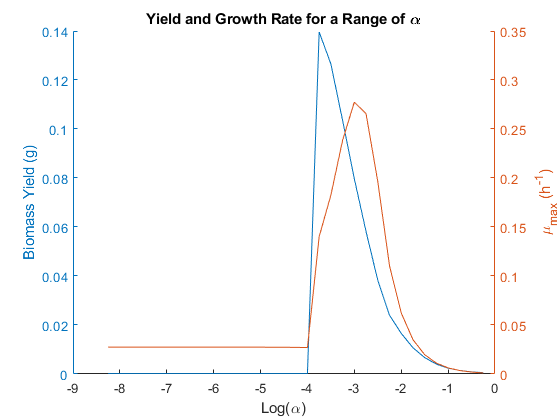

currentscale = 0.1250

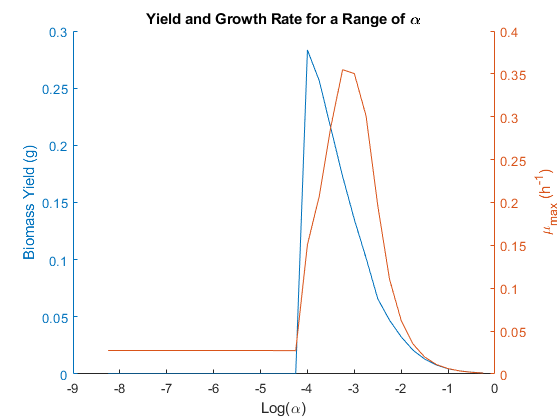

currentscale = 0.1250

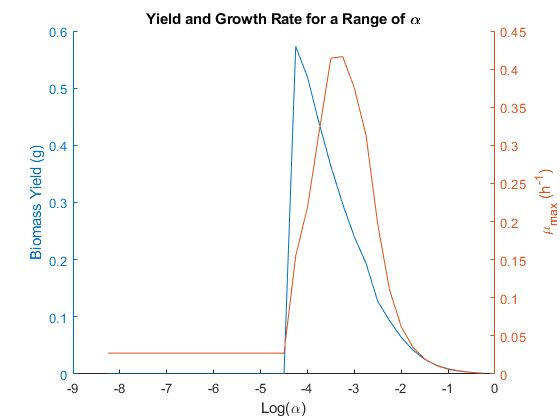

scales = unique(dat3.celscale);

for i = 1:length(scales)
    f = figure();
    hold on;
    currentscale = scales(1)
    d = dat3(dat3.celscale == scales(i),:); %Try at a differnt celscale?
    yyaxis left;
    plot(log10(d.alpha),d.biomass_max);
    ylabel('Biomass Yield (g)');
    yyaxis right;
    mu_max = cellfun(@(x) max(x),d.mu);
    plot(log10(d.alpha),mu_max);
    ylabel('\mu_m_a_x (h^-^1)');
    xlabel('Log(\alpha)');
    title('Yield and Growth Rate for a Range of \alpha');
    hold off;
end

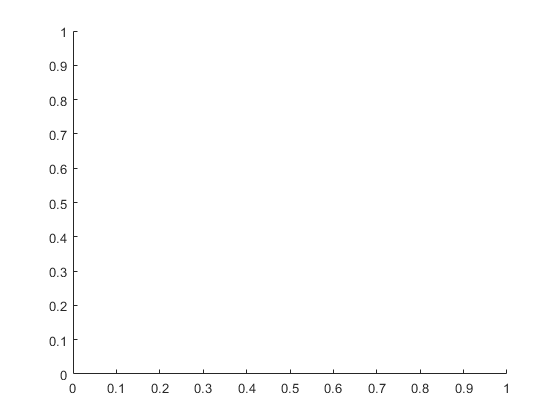


if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\two_measures','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\two_measures.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\two_measures.eps');%for LaTeX
end
cla reset; %kill the split y-axes

% %examine anomalous data spikes. Are they caused by the timesteps?
% if ~exist('dat3_compare','var')
%         load([datadir '\diagnostic data\dat3_compare_timesteps.mat']);
% end
% dat3_compare.yield = (dat3_compare.biomass_max - cellfun(@(x) x(1),dat3_compare.biomass))  ./ (dat3_compare.initcel * g_avicel_per_mol);
% 
% [nrows,~] = size(dat3_compare);
% colors = parula(1+nrows);
% figure();
% hold on;
% steplengths = zeros(nrows,1);
% for i = 1:nrows
%     plot(dat3_compare.t{i},log10(dat3_compare.biomass{i}),'color',colors(i,:),'LineWidth',2);
%     steplengths(i) = dat3_compare.t{i}(2);
% end
% hold off;
% xlabel('Time (hours)');
% ylabel('Log(Biomass) (g)');
% leg = legend(num2str(steplengths),'location','best');
% title(leg,'Timestep (h)');
% title('Comparison of biomass with different timesteps');
% 
% figure();
% hold on;
% steplengths = zeros(nrows,1);
% for i = 1:nrows
%     plot(dat3_compare.t{i}(1:end-1),log10(dat3_compare.biomass_delta{i}),'color',colors(i,:),'LineWidth',2);
%     steplengths(i) = dat3_compare.t{i}(2);
% end
% hold off;
% xlabel('Time (hours)');
% ylabel('Log(Growth Rate) (h^(-1))');
% leg = legend(num2str(steplengths),'location','best');
% title(leg,'Timestep (h)');
% title('Growth Rate with different timesteps');
% xlim([0,300])
% 
% figure();
% hold on;
% steplengths = zeros(nrows,1);
% for i = 1:nrows
%     plot(dat3_compare.t{i}(1:end-1),(dat3_compare.biomass_delta{i}),'-x','color',colors(i,:),'LineWidth',2);
%     steplengths(i) = dat3_compare.t{i}(2);
% end
% hold off;
% xlabel('Time (hours)');
% ylabel('Log(Growth Rate) (h^(-1))');
% leg = legend(num2str(steplengths),'location','best');
% title(leg,'Timestep (h)');
% title('Growth Rate with different timesteps');
% xlim([0,300])

What's going on where the alpha is so low the growth rate drops off?

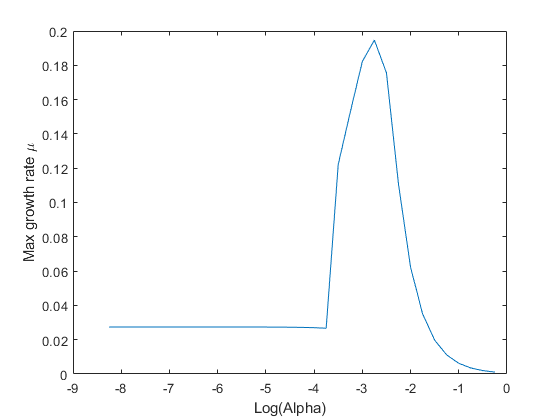

d = dat3_allrows(dat3_allrows.celscale == 1,:);
[nrows,~] = size(d);
d = sortrows(d,'alpha');
for i = 1:nrows
    d.mu{i} = d.biomass_delta{i} ./ d.biomass{i}(1:end-1);
    d.mu_max(i) = max(d.mu{i});
end
plot(log10(d.alpha),d.mu_max);
xlabel('Log(Alpha)');
ylabel('Max growth rate \mu');

hi = d(d.alpha == 10^-2.75,:); 
mid = d(d.alpha == 10^-3.5,:);
low = d(d.alpha == 10^-4,:);%manually estimated to be around the point where yield drops off

colors = lines(3);
colormap(colors);

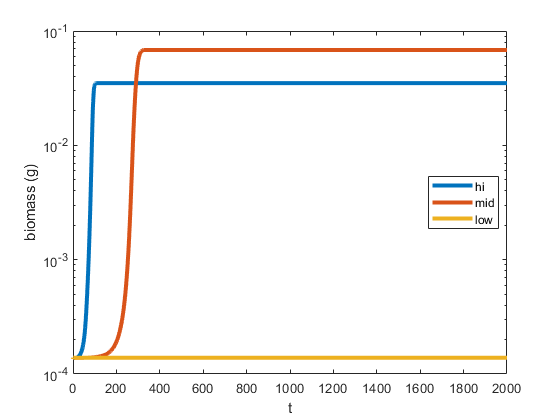

plot(hi.t{1},hi.biomass{1},mid.t{1},mid.biomass{1},low.t{1},low.biomass{1},'linewidth',3);
set(gca,'yscale','log');
legend({'hi' 'mid' 'low'},'location','best');
xlabel('t');
ylabel('biomass (g)');

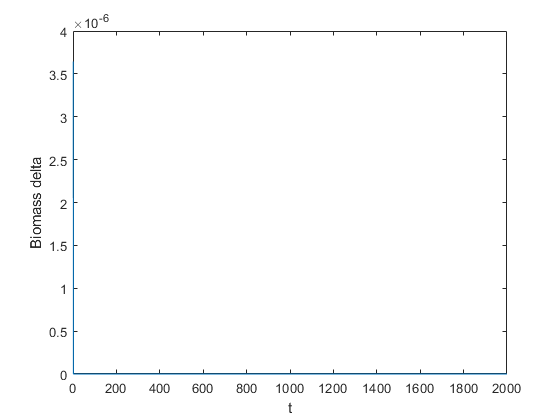


%is there any movement in the low series?
plot(low.biomass_delta{1});
xlabel('t');
ylabel('Biomass delta');

mean(low.biomass_delta{1})

ans = 1.8223e-09

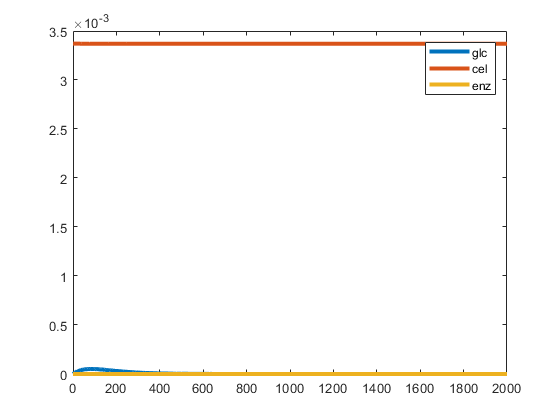

%When enzyme not in maint reaction: No, there's not.
%When enzyme is in the maint reaction: Yes, there is.

%check the other metabolites
t = low.t{1};
plot(t,low.glc_amt{1},t,low.cellulose_amt{1},t,low.enzyme_amt{1},'linewidth',3);
leg = legend({'glc' 'cel' 'enz'});

mean(low.enzyme_delta{1})

ans = 3.7560e-22

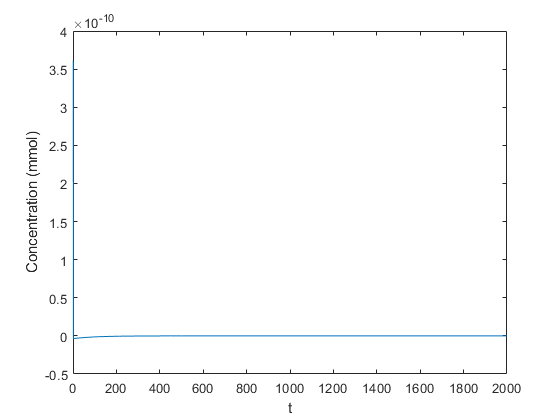

plot(low.enzyme_delta{1})
xlabel('t');
ylabel('Concentration (mmol)');

max(low.enzyme_delta{1})

ans = 3.6083e-10

%When enz not in maint: Enzyme amount never becomes positive

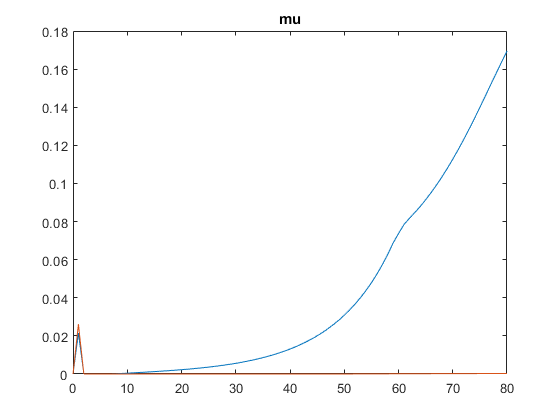

% What happens in the other series, at the start, in the race to get glc
% high enough to beat maintenance?
%Note: the critican glc numbers probably only apply to the enzyme-not-in-maintenance
%mode. Need to recalculate for enz-in-maint
plot(hi.t{1},[0; hi.mu{1}],mid.t{1},[0; mid.mu{1}])
title('mu')
xlim([0,80])

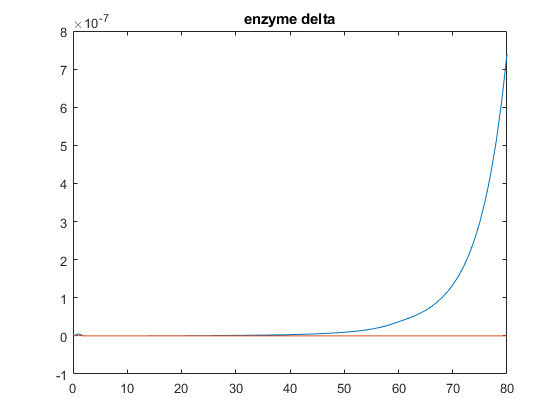

plot(hi.t{1},[0; hi.enzyme_delta{1}],mid.t{1},[0; mid.enzyme_delta{1}])
title('enzyme delta')
xlim([0,80])

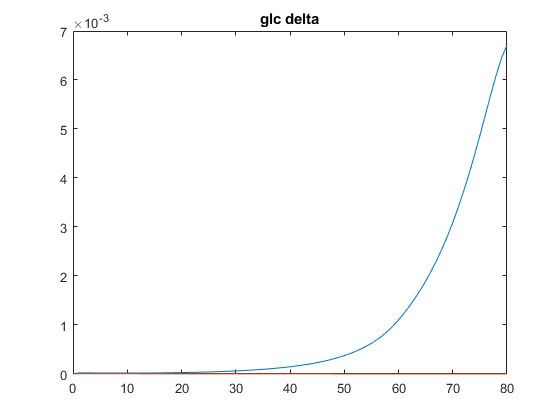

plot(hi.t{1},[0;hi.glc_delta{1}],mid.t{1},[0; mid.glc_delta{1}])
title('glc delta')
xlim([0,80])

plot(hi.t{1},hi.glc_amt{1},mid.t{1},mid.glc_amt{1})
title('glc concentration')
xlim([0,80])

%add series predicting the point where glc concentration crosses
%demand flux * biomass amt (roughly t=[25,65])
%Note this flux is slightly off bc it is the base model's demand, it
%doesn't take into account the increased demand from enzyme production that
%has been added to the maintenance reaction
%assuming default lb for maint rxn is 10
glcflux = 0.1545 * args.p3.v.initialpop; %units?
%glcflux = vmax * s/s+KM
%glcflux/vmax = s/s+KM = 1/(1+KM/s)
%vmax/glcflux = 1 + KM/s
%vmax/glcflux - 1= KM/s
%s = KM / (vmax/glcflux -1)
vmax = args.p3.v.vmax_glc * args.p3.v.initialpop;
critglc = args.p3.v.km_glc / ((vmax / glcflux) -1)

critglc = 1.5692e-05

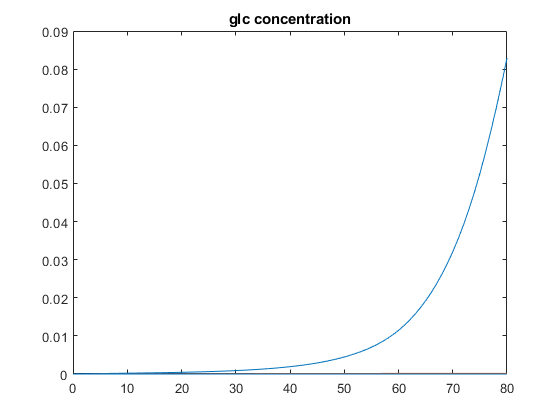


refline(0,critglc)
hold off;

Calculate the enzyme production rate based on growth

dat3.enzyme_secretion = cell(size(dat3.biomass_delta));
[nrows,~] = size(dat3);
for i = 1:nrows
    biodelta = dat3.biomass_delta{i};
    a = dat3.alpha(i);
    enzdelta = biodelta * a;
    dat3.enzyme_secretion{i} = enzdelta;
end


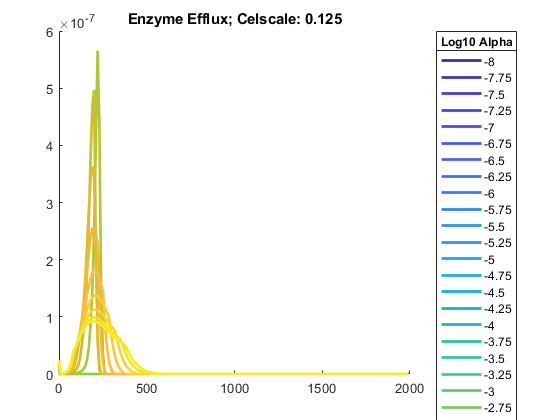

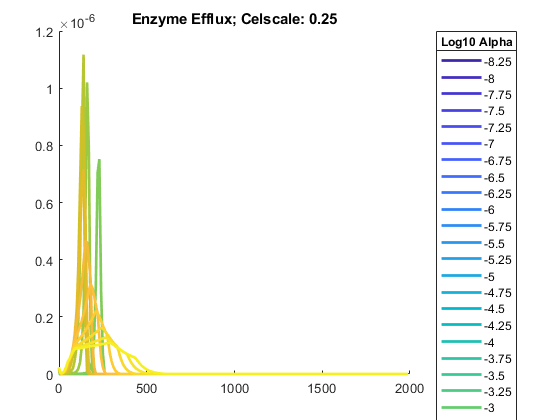

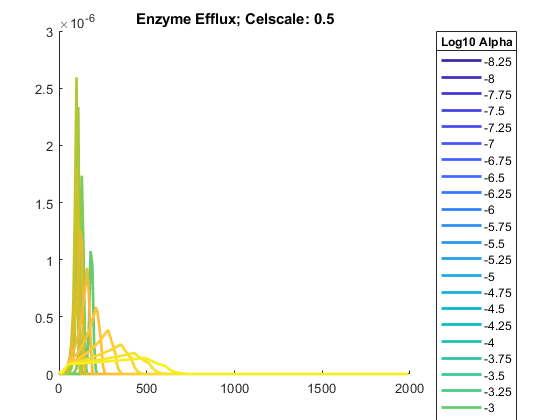

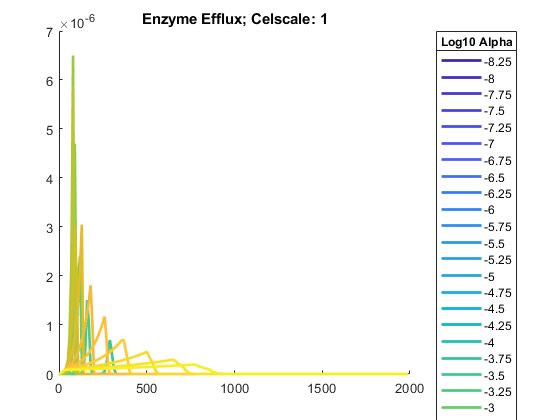

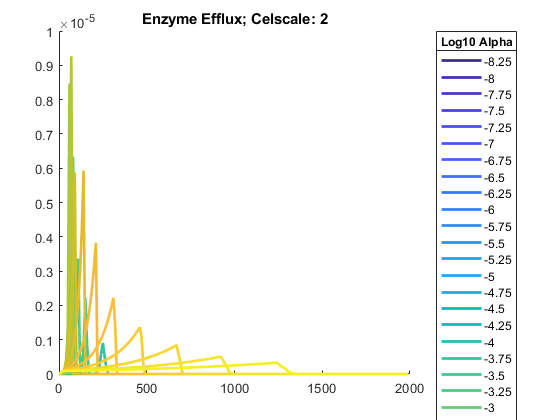

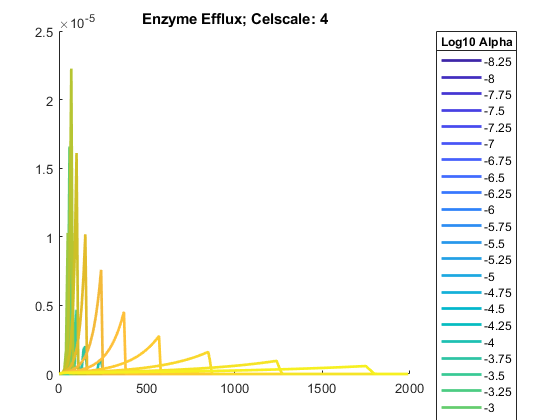

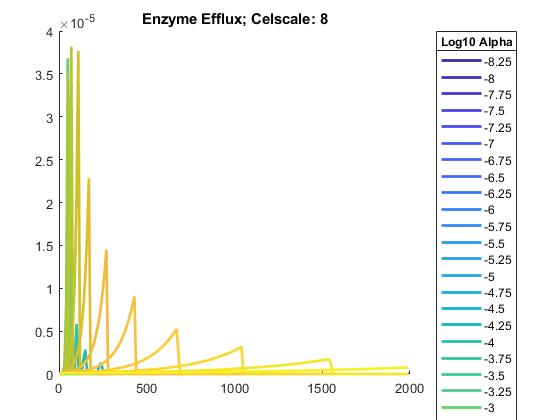

%plot the deltas
for s = 1:length(scales)
    scale = scales(s);
    subdat = dat3(dat3.celscale == scale,:);
    [nrows,~] = size(subdat);
    figure();
    hold on;
    title(['Enzyme Efflux; Celscale: ' num2str(scale)]);
    colors = parula(nrows+1);
    for i = 1:nrows
        row = subdat(i,:);
        disppoints = zeros(size(row.t{1}));
        [runtime,~] = size(disppoints);
        [biodeltalength,~] = size(row.biomass_delta{1});
        runtime = min(runtime,biodeltalength);
        disppoints(1:10:runtime-1) = 1;
        plot(row.t{1}(disppoints==1),row.enzyme_secretion{1}(disppoints==1),'DisplayName',num2str(log10(row.alpha(1))),'LineWidth',2,'color',colors(i,:));
    end
    leg=legend('location','eastoutside');
    title(leg,'Log10 Alpha');
    hold off;
end